##  Setting the number of followers

clear
clc
clf
number_of_followers = 6;
number_of_virtual = 1;
rng(1555)

 Setting the Path of the Leader

deltat = 0.01;
time_steps = 1:deltat:50+0.99;
r0 = [time_steps-5;-5+10*sin(time_steps*pi/25)].';
r0_new = zeros(1,2);
for i=1:size(r0,1)
    r0_new(:,:,i) = r0(i,:);
end
r0_new;

Generating the R_i matrix 

random_coords = rand(number_of_followers,2);
r_i = zeros(number_of_followers+number_of_virtual,2,size(time_steps,2));
r_i(2:end,:,1)= [random_coords(:,1)-5 random_coords(:,2)-5];
r_i(1,:,:) = r0_new

r_i = r_i(:,:,1) =

   -4.0000   -3.7467
   -4.9368   -4.7762
   -4.2393   -4.9421
   -4.4077   -4.0626
   -4.1428   -4.0455
   -4.0029   -4.0072
   -4.2314   -4.2346


r_i(:,:,2) =

   -3.9900   -3.7342
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


r_i(:,:,3) =

   -3.9800   -3.7217
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


r_i(:,:,4) =

   -3.9700   -3.7093
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


r_i(:,:,5) =

   -3.9600   -3.6968
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


r_i(:,:,6) =

   -3.9500   -3.6844
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


r_i(:,:,7) =

  

size(r_i)

ans =            7           2        5000


For predefined points

adj_matrix = zeros(7,7);
adj_matrix = [0 0 0 0 1 0 0;
              0 0 1 0 0 0 0;
              0 1 0 1 0 0 0;
              0 0 1 0 1 0 0;
              1 0 0 1 0 1 0;
              0 0 0 0 1 0 1;
              0 0 0 0 0 1 0];
r_i(2:end,:,1) = [16 -20;
                10 -15;
                5 -12;
                -2 8;
                -8 15;
                -12 20];

For Random points auto generate adj_matrix

% for i = 1:number_of_followers+number_of_virtual
%     for j = 1:number_of_followers+number_of_virtual
%         if(i==j)
%             continue
%         end
%         X = [r_i(i,:,1);r_i(j,:,1)];
%         adj_matrix(i,j) = pdist(X,"euclidean")<1.2;
%     end
% end
adj_matrix

adj_matrix =      0     0     0     0     1     0     0
     0     0     1     0     0     0     0
     0     1     0     1     0     0     0
     0     0     1     0     1     0     0
     1     0     0     1     0     1     0
     0     0     0     0     1     0     1
     0     0     0     0     0     1     0


G = graph(adj_matrix,{'leader','1','2','3','4','5','6'})

G =   graph with properties:

    Edges: [6×2 table]
    Nodes: [7×1 table]


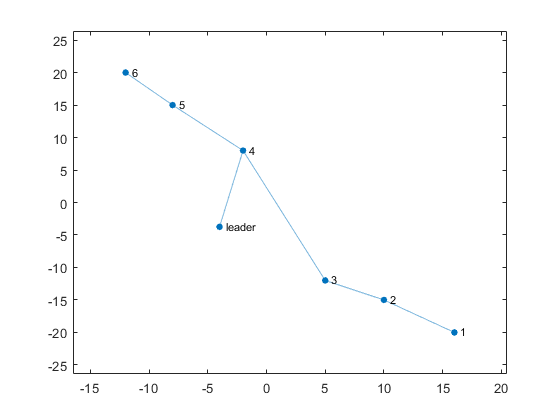

plot(G,'XData',r_i(:,1,1),'YData',r_i(:,2,1))

## Where $\dot{r}_i = u_i$

## 
$$u_i = -\alpha \sum_{j=0}^na_{ij}(r_i-r_j)-\beta sgn[\sum_{j=0}^na_{ij}(r_i-r_j)]$$


## 
$$\tilde{\dot{r}}_i = \dot{r_i} - \dot{r_0}$$


alpha = 1;
beta = 1.5;

laplacian_matrix = zeros(size(adj_matrix));
for i=1:7
    for j=1:7
        if(i==j)
           laplacian_matrix(i,j) = sum(adj_matrix(:,j),"all");
        else
           if(adj_matrix(i,j)>0)
               laplacian_matrix(i,j) = -1;
           else
               laplacian_matrix(i,j) = 0;
           end
        end
    end
end
% laplacian_matrix

m_matrix = laplacian_matrix +diag(adj_matrix(:,1));
m_matrix = m_matrix(2:end,2:end);

## Matrix Method

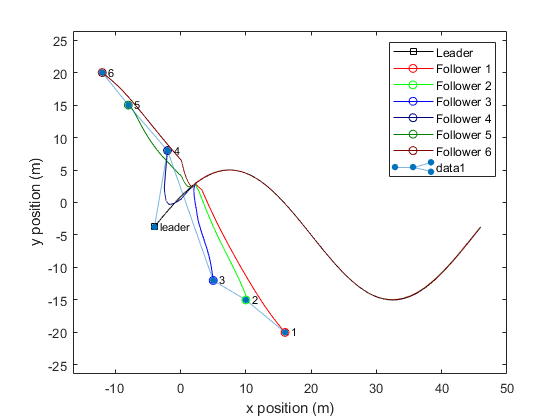

clf
hold off
for t=1:5000-1
   r_tilde = r_i(2:end,:,t)-r_i(1,:,t);
   r_tilde_dot = (-alpha.*m_matrix*r_tilde) - (beta.*sign(m_matrix*r_tilde))-((r_i(1,:,t+1)-r_i(1,:,t)));
   r_i(2:end,:,t+1) = (r_tilde_dot*deltat+(r_i(1,:,t+1)-r_i(1,:,t)))+r_i(2:end,:,t);
   plot(G,'XData',r_i(:,1,t),'YData',r_i(:,2,t),"NodeLabel",{'leader','1','2','3','4','5','6'});
   pause(0.0005)
end

Saving

% r_i(:,:,end)=[];
% save("Consensustrackingkinamatics","r_i")

## Plotting

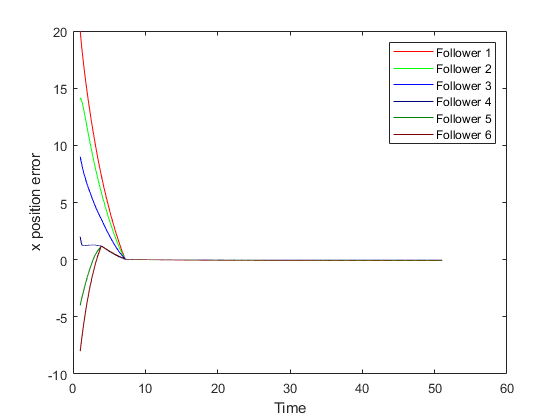

load("Consensustrackingkinamatics.mat","r_i")
colorrand =[0 0 0;1 0 0;0 1 0;0 0 1;0 0 0.5;0 0.5 0;0.5 0 0];
clf
for i=1:6
    plot(time_steps,reshape(r_i(i+1,1,:)-r_i(1,1,:),[],1),"Color",colorrand(i+1,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])
xlabel("Time")
ylabel("x position error")

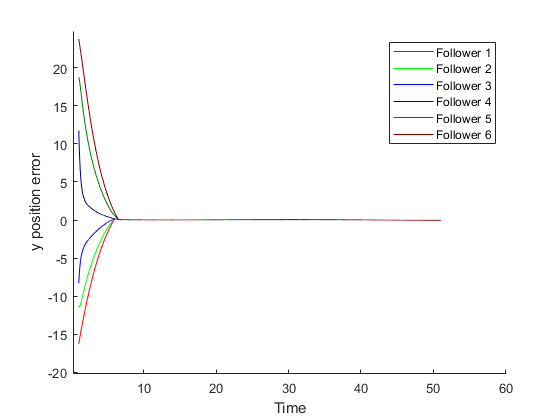

clf
hold on
for i=1:6
    plot(time_steps,reshape(r_i(i+1,2,:)-r_i(1,2,:),[],1),"Color",colorrand(i+1,:))    
    hold on
end
legend(["Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])

xlim([0.2 60.2])
ylim([-20.2 24.8])
xlabel("Time")
ylabel("y position error")

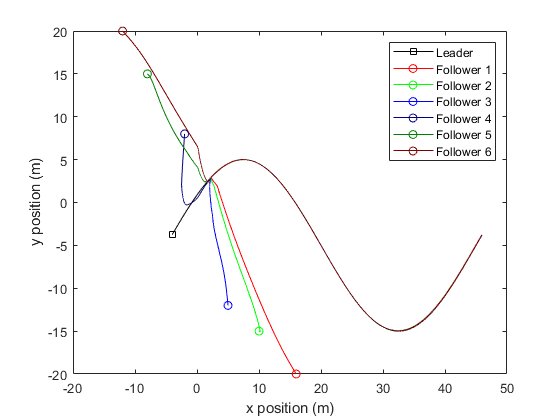

clf
hold off
    plot(reshape(r_i(1,1,:),[],1),reshape(r_i(1,2,:),[],1),"Color",colorrand(1,:),"Marker","square","MarkerIndices",1)
hold on
for i=2:7
    plot(reshape(r_i(i,1,:),[],1),reshape(r_i(i,2,:),[],1),"Color",colorrand(i,:),"Marker","o","MarkerIndices",1)
end
legend(["Leader","Follower 1","Follower 2","Follower 3","Follower 4","Follower 5","Follower 6"])
xlabel("x position (m)")
ylabel("y position (m)")